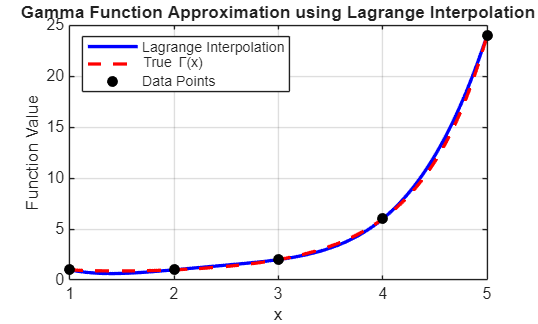

% Define the data points from the Gamma function definition
x = [1 2 3 4 5];
f = [1 1 2 6 24]; % Gamma(n) = (n-1)!

% Define points where we want to evaluate the interpolating polynomial
u = linspace(1, 5, 200);

% Call the interpolation function
v = polyinterp(x, f, u);

% Compute actual Gamma function values
gamma_true = gamma(u);

% Plot results
figure;
plot(u, v, 'b-', 'LineWidth', 2); hold on;
plot(u, gamma_true, 'r--', 'LineWidth', 2);
plot(x, f, 'ko', 'MarkerFaceColor', 'k');
legend('Lagrange Interpolation', 'True \Gamma(x)', 'Data Points', 'Location', 'northwest');
xlabel('x');
ylabel('Function Value');
title('Gamma Function Approximation using Lagrange Interpolation');
grid on;


% ------------ FUNCTION DEFINITION BELOW ------------
function v = polyinterp(x, f, u)
    n = length(x);
    m = length(u);
    v = zeros(size(u));

    for k = 1:m
        s = 0;
        for j = 1:n
            p = 1;
            for i = [1:j-1, j+1:n]
                p = p * (u(k) - x(i)) / (x(j) - x(i));
            end
            s = s + f(j) * p;
        end
        v(k) = s;
    end
end
